%% Inverted Pendulum (Cart-Pole) Controller Shootout
% PID-style (two-loop PD), Pole Placement, and LQR on the NONLINEAR plant.
% One-file, paste-and-run.
%
% Requires: Control System Toolbox (for lqr/place)
%
% Upright equilibrium is theta = 0 (pendulum pointing UP).

clear; clc; close all;

%% -------------------- Parameters --------------------
P.M = 0.5;     % cart mass (kg)
P.m = 0.2;     % pendulum mass (kg)
P.l = 0.3;     % distance pivot->COM (m)
P.I = 0.006;   % inertia about COM (kg*m^2)
P.b = 0.1;     % cart viscous friction (N*s/m)
P.g = 9.81;    % gravity (m/s^2)

P.umax = 10;   % actuator saturation (N)
P.tspan = [0 10];

% Initial condition: [x; xdot; theta; thetadot]
x0 = [0; 0; deg2rad(8); 0];

odeOpts = odeset('RelTol',1e-7,'AbsTol',1e-8);

%% -------------------- Linearize about upright --------------------
[A,B] = lin_cartpole_fd(P);

fprintf("Controllability rank = %d (should be 4)\n", rank(ctrb(A,B)));

Controllability rank = 4 (should be 4)



%% -------------------- Controllers --------------------
% LQR
Q = diag([1, 1, 200, 10]);
R = 0.1;
Klqr = lqr(A,B,Q,R);

% Pole placement
poles = [-2, -2.5, -5, -6];
Kpp = place(A,B,poles);

% PID-style (really 2-loop PD: cart centering + angle stabilization)
% u = -(Kpx*x + Kdx*xdot + Kpt*theta + Kdt*thetadot)
Kpx = 1;   Kdx = 2;
Kpt = 50;  Kdt = 10;
Kpid = [Kpx Kdx Kpt Kdt];

%% -------------------- Run simulations --------------------
[tlqr, xlqr, ulqr] = sim_nonlinear(P, x0, odeOpts, @(t,x) sat(-Klqr*x, P.umax));
[tpp,  xpp,  upp ] = sim_nonlinear(P, x0, odeOpts, @(t,x) sat(-Kpp*x,  P.umax));
[tpid, xpid, upid] = sim_nonlinear(P, x0, odeOpts, @(t,x) sat(-(Kpid*x), P.umax));

%% -------------------- Metrics --------------------
mLQR = metrics(tlqr, xlqr, ulqr);
mPP  = metrics(tpp,  xpp,  upp);
mPID = metrics(tpid, xpid, upid);

Results = table( ...
    ["LQR";"PolePlace";"2loopPD"], ...
    [mLQR.MaxThetaDeg; mPP.MaxThetaDeg; mPID.MaxThetaDeg], ...
    [mLQR.SettleTimeTheta; mPP.SettleTimeTheta; mPID.SettleTimeTheta], ...
    [mLQR.MaxX; mPP.MaxX; mPID.MaxX], ...
    [mLQR.IntU2; mPP.IntU2; mPID.IntU2], ...
    [mLQR.FellOver; mPP.FellOver; mPID.FellOver], ...
    'VariableNames', ["Controller","MaxThetaDeg","SettlingTime_s","MaxX_m","IntU2","FellOver"] ...
);
disp(Results);

    Controller     MaxThetaDeg    SettlingTime_s     MaxX_m      IntU2      FellOver
    ___________    ___________    ______________    ________    ________    ________

    "LQR"                 8          0.33019        0.088238    0.045959     false  
    "PolePlace"           8           1.0095        0.030482    0.020474     false  
    "2loopPD"        254.87              NaN          208.39      376.09     true   



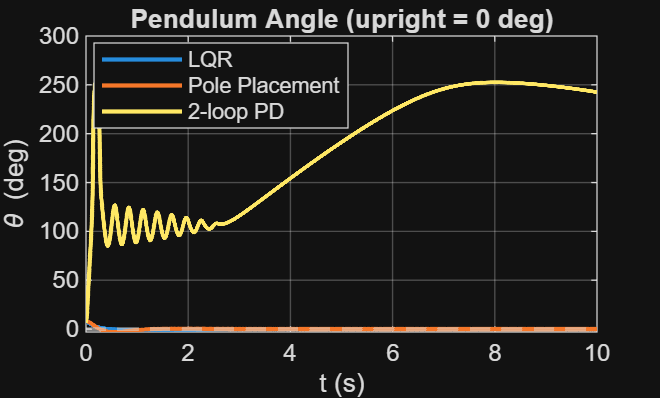


%% -------------------- Plots --------------------
figure; 
plot(tlqr, rad2deg(xlqr(:,3)), 'LineWidth', 1.6); hold on;
plot(tpp,  rad2deg(xpp(:,3)),  'LineWidth', 1.6);
plot(tpid, rad2deg(xpid(:,3)), 'LineWidth', 1.6);
yline(1,'--'); yline(-1,'--');
grid on; xlabel('t (s)'); ylabel('\theta (deg)');
title('Pendulum Angle (upright = 0 deg)');
legend('LQR','Pole Placement','2-loop PD','Location','best');

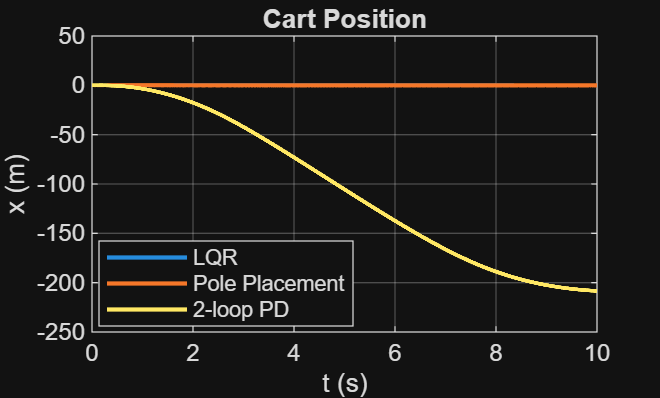


figure;
plot(tlqr, xlqr(:,1), 'LineWidth', 1.6); hold on;
plot(tpp,  xpp(:,1),  'LineWidth', 1.6);
plot(tpid, xpid(:,1), 'LineWidth', 1.6);
grid on; xlabel('t (s)'); ylabel('x (m)');
title('Cart Position');
legend('LQR','Pole Placement','2-loop PD','Location','best');

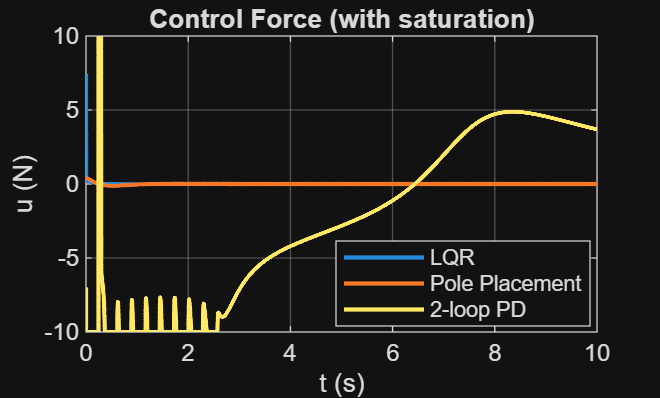


figure;
plot(tlqr, ulqr, 'LineWidth', 1.6); hold on;
plot(tpp,  upp,  'LineWidth', 1.6);
plot(tpid, upid, 'LineWidth', 1.6);
yline(P.umax,'--'); yline(-P.umax,'--');
grid on; xlabel('t (s)'); ylabel('u (N)');
title('Control Force (with saturation)');
legend('LQR','Pole Placement','2-loop PD','Location','best');

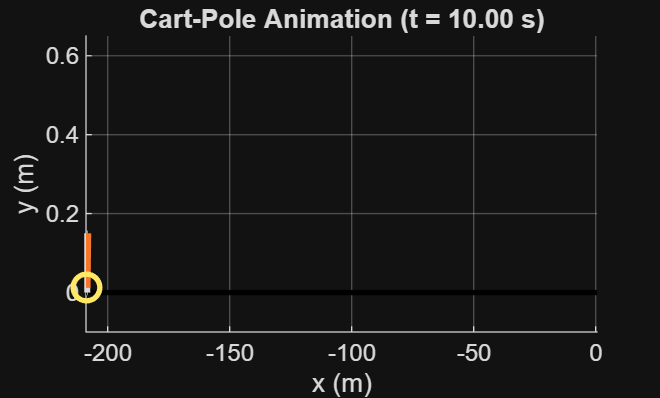


%% -------------------- Animation (pick controller) --------------------
% Choose one to animate:
% animate_cartpole(P, tlqr, xlqr);   % LQR
% animate_cartpole(P, tpp,  xpp);    % Pole placement
animate_cartpole(P, tpid, xpid);     % 2-loop PD



%% ====================================================================
%%                         Local Functions
%% ====================================================================

function [t, x, u] = sim_nonlinear(P, x0, odeOpts, ctrl)
% Simulate nonlinear cart-pole with control law u = ctrl(t,x)

ode = @(t,x) closedloop_ode(t, x, P, ctrl);
[t, x] = ode45(ode, P.tspan, x0, odeOpts);

u = zeros(size(t));
for k = 1:length(t)
    u(k) = ctrl(t(k), x(k,:)');
end
end

function dx = closedloop_ode(t, x, P, ctrl)
u = ctrl(t,x);
dx = cartpole_nl(t, x, u, P);
end

function dx = cartpole_nl(~, x, u, P)
% x = [pos; vel; theta; theta_dot]
M = P.M; m = P.m; l = P.l; I = P.I; b = P.b; g = P.g;

pos = x(1); %#ok<NASGU>
vel = x(2);
th  = x(3);
thd = x(4);

p = I + m*l^2;

den_x = (M+m) - (m^2*l^2*cos(th)^2)/p;
xdd = (u - b*vel + m*l*thd^2*sin(th) - m*g*l*sin(th)*cos(th)) / den_x;

thdd_num = (M+m)*g*l*sin(th) - cos(th)*(u - b*vel + m*l*thd^2*sin(th));
thdd_den = p*(M+m) - m^2*l^2*cos(th)^2;
thdd = thdd_num / thdd_den;

dx = [vel; xdd; thd; thdd];
end

function [A,B] = lin_cartpole_fd(P)
% Finite-difference linearization of xdot = f(x,u) about upright equilibrium
x0 = [0;0;0;0];
u0 = 0;

f = @(x,u) cartpole_nl(0,x,u,P);

eps = 1e-6;
A = zeros(4);
B = zeros(4,1);

fx0 = f(x0,u0);
for i=1:4
    dx = zeros(4,1); dx(i)=eps;
    A(:,i) = (f(x0+dx,u0) - fx0)/eps;
end
B(:,1) = (f(x0,u0+eps) - fx0)/eps;
end

function y = sat(u, umax)
y = max(min(u, umax), -umax);
end

function M = metrics(t, x, u)
theta_deg = rad2deg(x(:,3));
M.MaxThetaDeg = max(abs(theta_deg));
M.MaxX = max(abs(x(:,1)));
M.IntU2 = trapz(t, u.^2);

% Settling time: theta within +-1 deg and stays there
band = 1; % deg
idx = find(abs(theta_deg) > band, 1, 'last');
if isempty(idx)
    M.SettleTimeTheta = 0;
elseif idx == length(t)
    M.SettleTimeTheta = NaN; % never settled
else
    M.SettleTimeTheta = t(idx+1);
end

% "fell over" condition
M.FellOver = any(abs(theta_deg) > 30);
end

function animate_cartpole(P, t, x)
% Simple cart-pole animation.
% Cart at position x(t), pendulum angle theta(t), upright theta=0.

l = P.l;
cartW = 0.3; cartH = 0.15;
y0 = 0;              % ground
pivotY = y0 + cartH; % pivot height on cart

% axis limits based on cart travel
xlim_ = [min(x(:,1))-0.5, max(x(:,1))+0.5];
ylim_ = [-0.1, cartH + l + 0.2];

figure;
for k = 1:5:length(t)
    clf; hold on; grid on;
    axis([xlim_ ylim_]);
    xlabel('x (m)'); ylabel('y (m)');
    title(sprintf('Cart-Pole Animation (t = %.2f s)', t(k)));

    % ground
    plot(xlim_, [y0 y0], 'k-', 'LineWidth', 2);

    % cart
    cx = x(k,1);
    rectangle('Position',[cx-cartW/2, y0, cartW, cartH], ...
              'Curvature', 0.05, 'LineWidth', 2);

    % pendulum
    th = x(k,3);
    px = cx;
    py = pivotY;

    bx = px + l*sin(th);
    by = py + l*cos(th);

    plot([px bx],[py by], 'LineWidth', 3);
    plot(bx, by, 'o', 'MarkerSize', 10, 'LineWidth', 2);

    drawnow;
end
end
